# **Práctica 2: Análisis de la respuesta frecuencial de un sistema de control digital**

Las prácticas de la asignatura Control con Computador consisten en el estudio de un servomecanismo de posicionamiento angular (LJ Technical Systems) controlado por un PC. Las sesiones de laboratorio P1 y P2 se centran en el análisis experimental de las respuestas temporal y frecuencial del sistema respectivamente. La sesión P3 se dedica al diseño de controladores PID.

**OBJETIVO: Análisis de la respuesta frecuencial del sistema de control digital de velocidad. Análisis de la estabilidad mediante el criterio de Nyquist.**

**En esta sesión el estudiante ha de:**

- **Encontrar experimentalmente la respuesta frecuencial del sistema en lazo abierto.**

- **Aplicar el criterio de Nyquist para determinar el rango de valores de un controlador proporcional para que el sistema en lazo cerrado sea estable, y verificarlo experimentalmente.**

- **Comparar los resultados obtenidos con los resultados teóricos.**

# Ejercicio 7: Obtención del diagrama de Nyquist

Usando los valores del modelo de la práctica 1 representar en un mismo valor la respuesta frecuencial de:

- El sistema en lazo abierto de velocidad de tiempo continuo.

- El sistema en lazo abierto de tiempo discreto con el periodo de muestreo de $T_s =0,01$.

- Identificar sobre las gráficas las zonas correspondientes a frecuencias altas y bajas.

- Justificar las diferencias que se observan entre las gráficas en cada una de las bandas de frecuencias.

% Parámetros de la planta
K_mot=0.82; %[rpm/V]
T_mot=0.24; %seg

% Periodo de muestreo
Ts=0.01;

% Función de transferencia analógico y digital del modelo
F=tf([K_mot],[T_mot 1])


F =
 
     0.82
  ----------
  0.24 s + 1
 
Continuous-time transfer function.



Fd=c2d(F,Ts)


Fd =
 
   0.03346
  ----------
  z - 0.9592
 
Sample time: 0.01 seconds
Discrete-time transfer function.



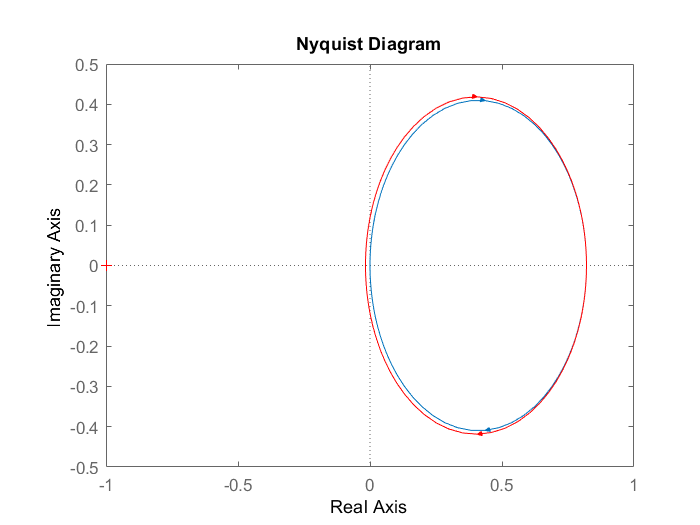


% Diagramas de Nyquist
figure
nyquist(F)
hold on 
nyquist(Fd,'red')

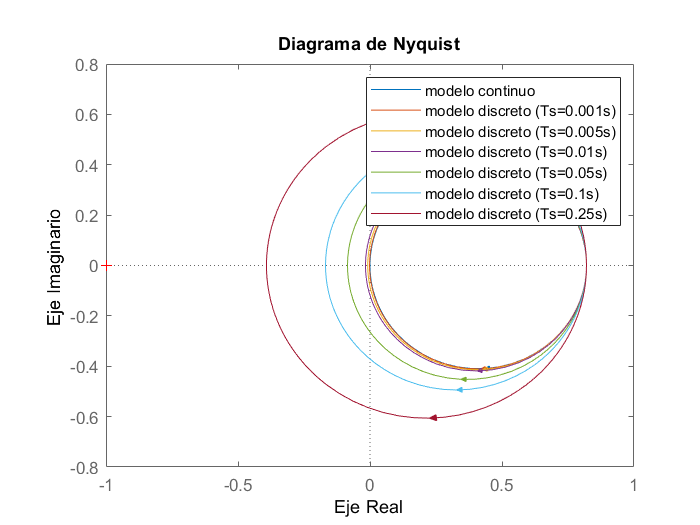


% Visualizamos el Nyquist para diferentes períodos de muestreo
    i=1;
    Ts=[0.001 0.005 0.01 0.05 0.1 0.25];
    [fils cols]=size(Ts);
    llegenda={'modelo continuo'};
    while (i<=cols)
        llegenda={char(llegenda);strcat(strcat('modelo discreto (Ts=',num2str(Ts(1,i))),'s)')};
        i=i+1;
    end
    llegenda=char(llegenda);
    figure(2);
    nyquist(F);
    hold on;
    %legend('model continu');
    i=1;        
    while (i<=cols)
        nyquist(c2d(F,Ts(1,i),'zoh'));
        % legend(strcat(strcat('model discret(Ts=',num2str(Ts(1,i))),'s)'));
        i=i+1;
    end
    legend(llegenda);
    title('Diagrama de Nyquist');
    xlabel('Eje Real');
    ylabel('Eje Imaginario');

# Ejercicio 8: Obtención experimental del diagrama de Nyquist del sistema discreto

Abrir y ejecutar el modelo P2_Ex8.slx. Generar una señal senoidal de entrada de amplitud 2V y frecuencia 0,25Hz. Medir la ganancia y desfase de la señal de salida. Repetir el proceso para las frecuencias de 0.5, 0.8, 1, 2, 4, 5, 10, 20 y 50Hz. Usar un periodo de muestreo de 0,01 segundos.

open P2_Ex8.slx

% Vector de ganancias experimentales
G=[0.8 0.7 0.6 0.54 0.34 0.2 0.16 0.085 0.06];
% Vector de desfases experimentales (en radianes)
F=[18.45 32.4 46.08 52 68.4 86.4 108 126 144]*(-pi/180);
% Cálculo del complejo en forma cartesiana
X=real (G.*exp(F*j));
Y=imag(G.*exp(F*j));

% Introducción de los parámetros de la planta


planta =
 
     0.82
  ----------
  0.26 s + 1
 
Continuous-time transfer function.



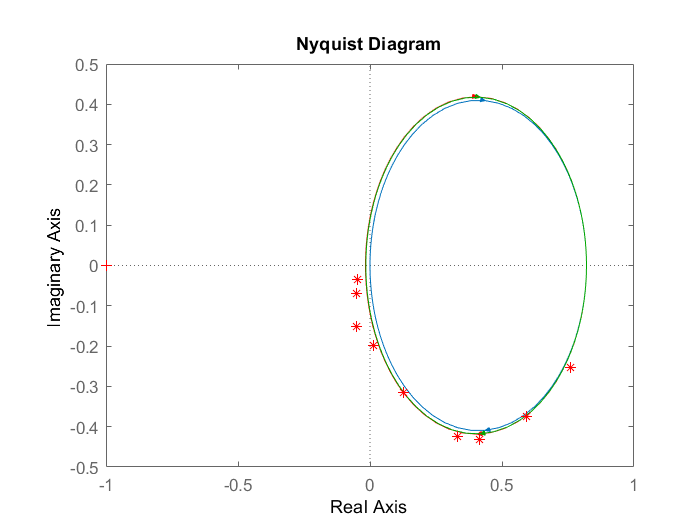

K0=0.82;
tau0=0.26;
planta=tf([K0],[tau0,1])

% Modelos de tiempo discreto
Ts=0.01;
plantad=c2d(planta,Ts,'zoh');

% Dibujamos el diagrama de Nyquist teórico y experimental
figure(1)

nyquist(plantad,'g')
hold on
plot(X,Y, 'r*' )


# Ejercicio 9: Aplicación del criterio de Nyquist

Usando el diagrama teórico aplicar el criterio de Nyquist para:

- Analizar la estabilidad del sistema de tiempo discreto.

- Encontrar el rango de valores del controlador proporcional $K_P$ que hacen que el sistema de tiempo discreto en lazo cerrado con realimentación de velocidad sea estable.

Compararlo con el caso de tiempo continuo comprobando cómo varían los diagramas teóricos al aumentar $K_P$. Verificar el resultado analizando la respuesta a escalón para $K_P$=5 y para un valor de $K_P$ fuera del rango, tanto en simulación como experimentalmente.

open P2_Ex9.slx


planta =
 
     0.82
  ----------
  0.26 s + 1
 
Continuous-time transfer function.



Ts = 0.0100

% Máximo Kp


sistemadiscreto =
 
   0.03094
  ----------
  z - 0.9623
 
Sample time: 0.01 seconds
Discrete-time transfer function.



planta=tf(0.82,[0.26 1])

gain = -0.0158

Ts=0.01

Kp_limit = 63.4225

sistemadiscreto=c2d(planta,Ts,'zoh')
gain=real(freqresp(sistemadiscreto,pi/Ts))
Kp_limit=-1/gain

# Ejercicio 10: Obtención del diagrama de Bode teórico

Usando el modelo del sistema y la transformación bilineal $\mathrm{d2c}\left(\ldotp \ldotp \ldotp ,\mathrm{'Tustin'}\right)$, representar graficamente el diagrama de Bode y determinar a partir de este diagrama el margen de ganancia y el margen de fase. Relacionar el margen de ganancia con el $K_P$ crítico del apartado anterior.

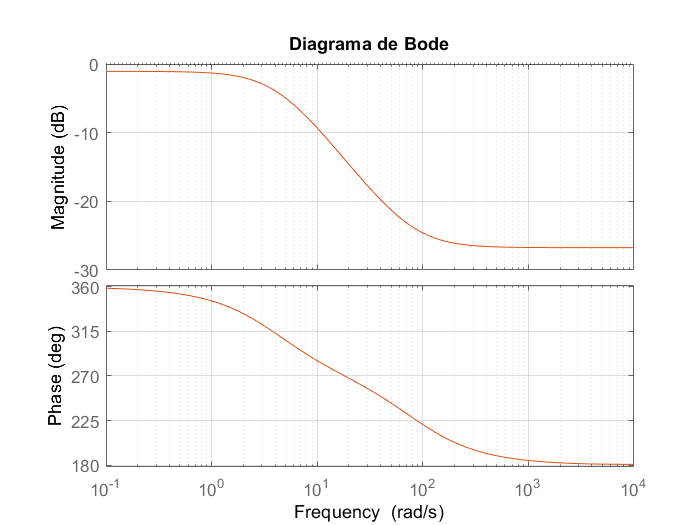

clc;
close all;
clear all;
% Modelo del sistema (abrimos archivo creado en la práctica 1: ejercicio 4)
    K0=52;
    tau0=0.24;
    Kt=0.017;
    Kp=1;
    planta=tf([K0],[tau0 1]);
% Frecuencia y periodo de muestreo
Fs=1/0.025;
Ts=1/Fs;

% Montaje del sistema teórico
sistema_continu=planta*Kt;
sistema_discret=c2d(sistema_continu,Ts,'zoh');
sistema_bilineal=d2c(sistema_discret,'tustin');

% Imagen del Bode los márgenes de fase / ganancia
figure(1);
bode(sistema_bilineal);
hold on;
grid on;
[Gm,Pm,Wcg,Wcp]=margin(sistema_bilineal);
margin(sistema_bilineal);
title('Diagrama de Bode');

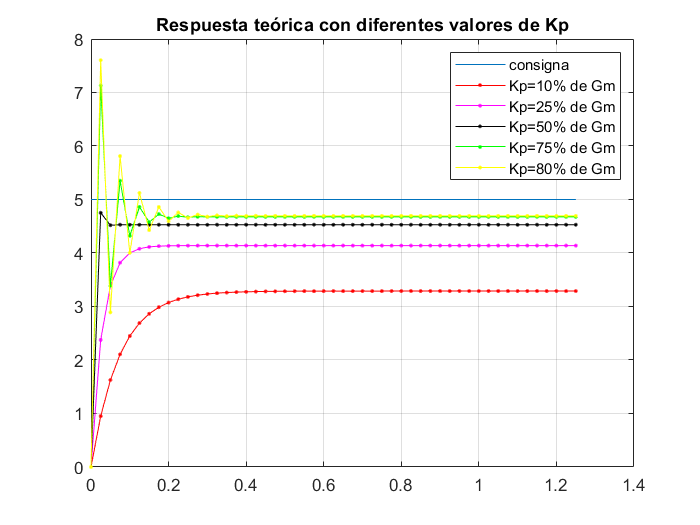


Vmax=5;
% Definimos un tiempo
Tx=0.0:Ts:50*Ts;
% Definimos unas consignas (escalón de altura Vmax)
X =[Vmax*ones(size(Tx))];
% Definimos un conjunto de Kp's con las cuales queremos 
% simular el sistema, expresadas como porcentaje de Gm (ó Kp_max)
Kp=[10 25 50 75 80]';
Kp=[Kp (1/100)*Kp*Gm];
% simulamos el comportamiento del sistema para diferentes kp's
[fils cols]=size(Kp);
i=1;
% el vector Y almacena las respuestas del sistema ante la consigna 
% con diferentes constantes de proporcionalidad
Y=[];
while (i<=fils)
    % la función model_discret(...) contiene una modelización del sistema en lazo
    % cerrado y controlador proporcional
    Y=[Y; Kt*model_discret(0,K0,Kp(i,2),Kt,tau0,Ts,X)];
    i=i+1;
end

figure(2);
T_MAX=max(Tx);
T_MIN=min(Tx);
Y_MAX=max(max(Y));
Y_MIN=min(min(Y));

% Dibujamos la consigna
plot(Tx,X);
hold on;
grid on;
% Dibujamos las simulaciones del sistema
i=1;
styles=['r.-';'m.-';'k.-';'g.-';'y.-';'c.-'];
[sty_fil sty_col]=size(styles);
llegenda={'consigna'};
while (i<=fils)
    plot(Tx,Y(i,:),styles(mod(i,sty_fil),:));
    llegenda={char(llegenda);strcat(strcat('Kp=',num2str(Kp(i,1))),'% de Gm')};
    i=i+1;
end
title('Respuesta teórica con diferentes valores de Kp');
llegenda=char(llegenda);
legend(llegenda);

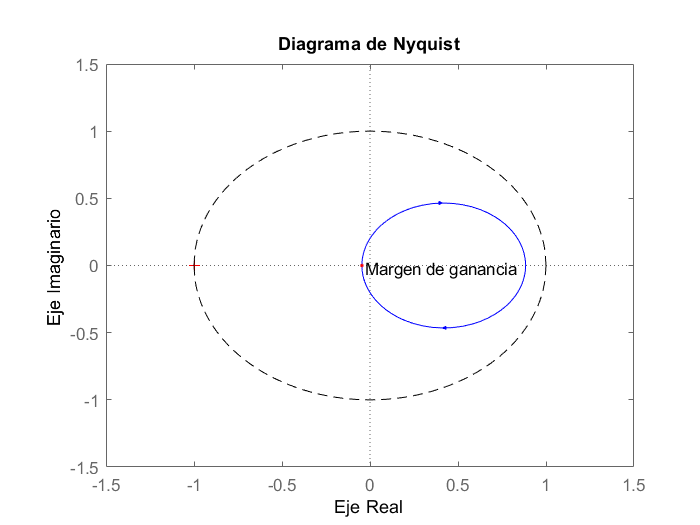


% Nyquist del sistema discreto
figure(3);
hold on;
nyquist(sistema_discret,'b-');
freq_resp=freqresp(sistema_discret,Wcp);
point=[real(freq_resp) imag(freq_resp)];
% Dibujamos el punto correspondiente al margen de fase y margen de ganancia
text(point(1,1)+0.02,point(1,2)-0.02,'Margen de fase');
plot(point(1,1),point(1,2),'r.');
freq_resp=freqresp(sistema_discret,pi/Ts);
point=[real(freq_resp) imag(freq_resp)];
text(point(1,1)+0.02,point(1,2)-0.02,'Margen de ganancia');
plot(point(1,1),point(1,2),'r.');
axis([-1.5 1.5 -1.5 1.5]);
title('Diagrama de Nyquist');
xlabel('Eje Real');
ylabel('Eje Imaginario');
x=[0 point(1,1)]';
y=[0 point(1,2)]';
circumf;